clear all;

%GLOBAL
pdm_data = fopen('silence.bmp', 'r');
f_s = 3.175 * 10^6;
f_pdm = f_s/2;
f_cut = f_pdm / 100;
pdm_store_size = 24;%bit
register_size=32;%bit
cnt_additional_samples = 4000% 28*pdm_store_size;

cnt_additional_samples = 4000

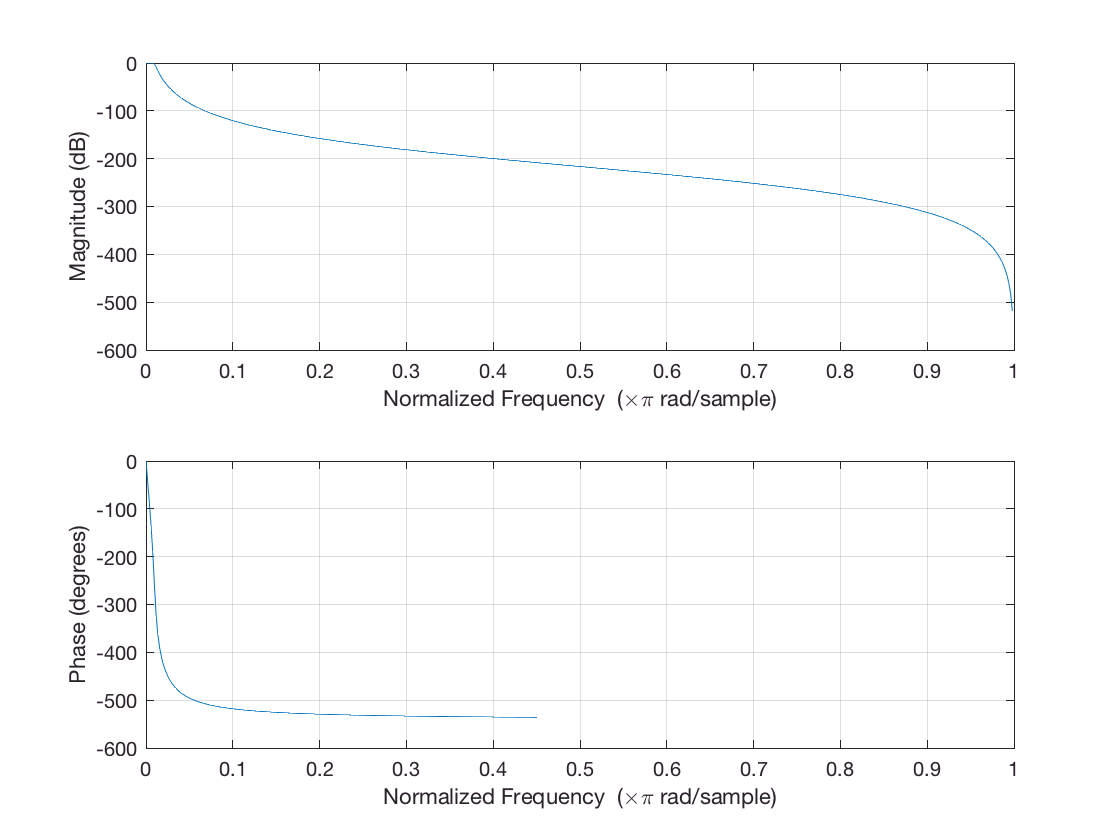

% [b, a] = butter(6,100/(0.5*230),'low');
[b, a] = butter(6,f_cut/(f_s/2),'low');
%--END GLOBAL 

% see filter
freqz(b,a) 

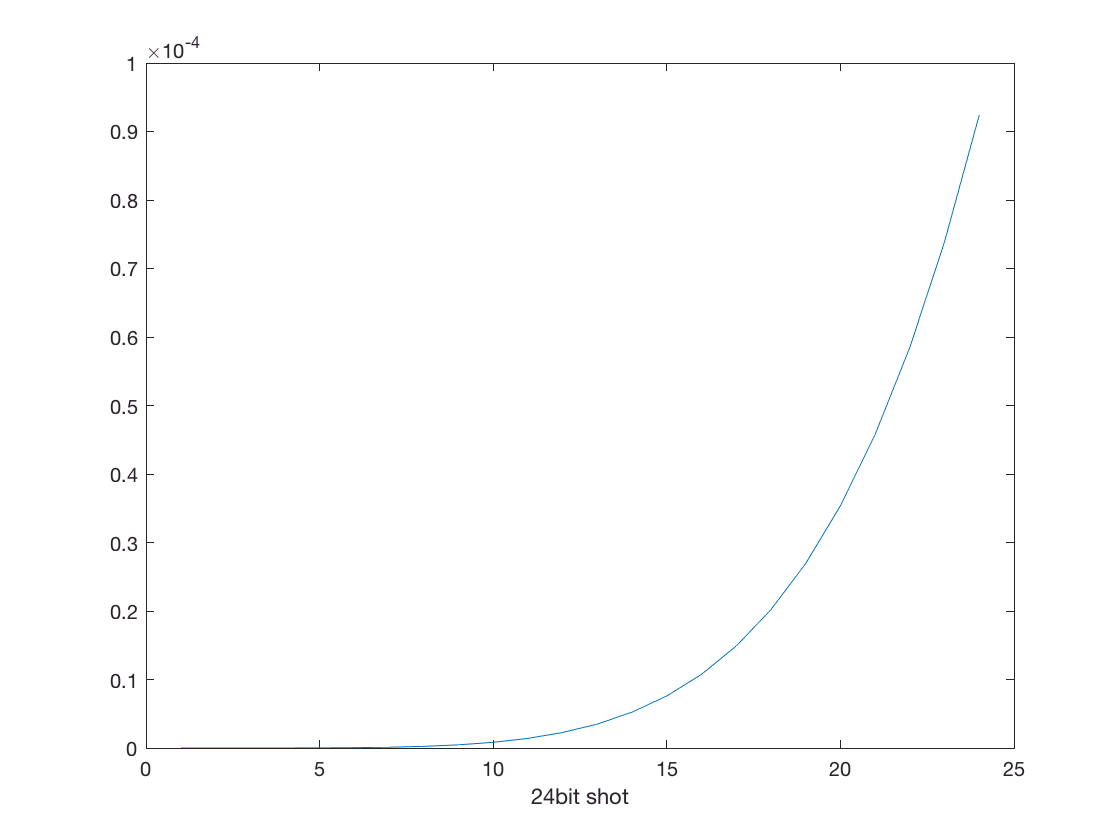

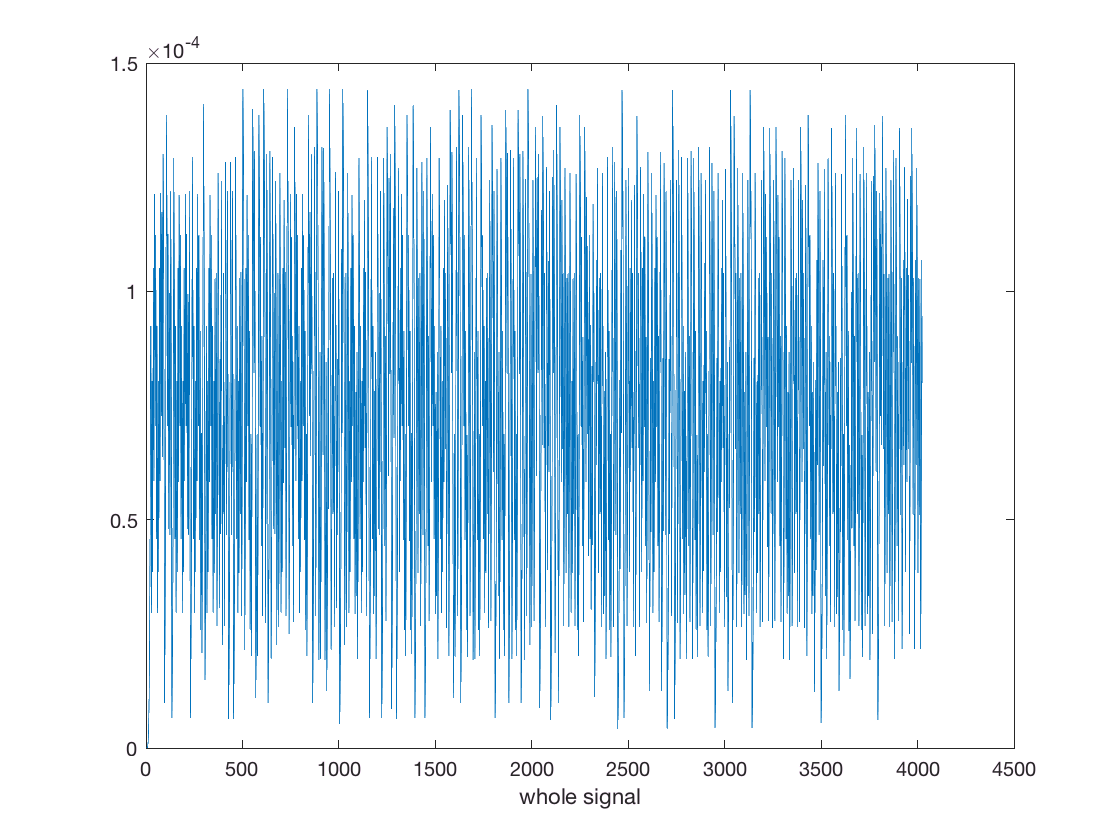

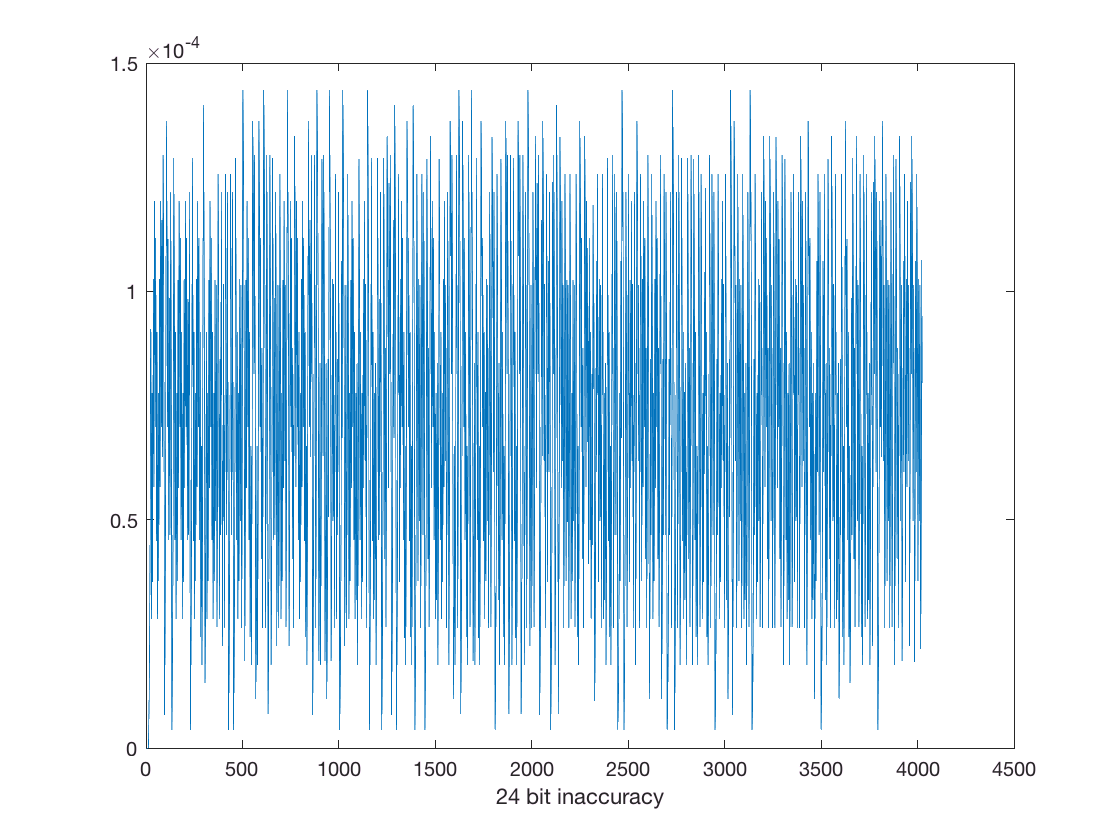



%Get First 24bit
signal = get_pdm(pdm_store_size, pdm_data);

%MATLAB OUTPUT data to prober plot this shit
Output_data = zeros(cnt_additional_samples,pdm_store_size);
foo = zeros(cnt_additional_samples,pdm_store_size);
foo(1,1:end) = signal; 
y = custom_filter_array(signal,a,b);
Output_data(1,1:end) = y;

%get next pdm value
for i=2:cnt_additional_samples
    % ---- old version ----
    %x = zeros(1,pdm_store_size);
    %x(1,1:end) = double(rand(1,pdm_store_size)>0.5); 
    %ret=x;
    
    % ---- new version ----
%     pdm_data = fopen('pdm_data.txt');
%     x = zeros(1,pdm_store_size);
%     x(1,1:end) = fread(pdm_data, pdm_store_size, '*ubit1', 'ieee-be');
%     ret=x;
    
%      next_input = double(rand(1,1)>0.5);
     next_input = get_pdm(1, pdm_data);
     
     %shift signal
     signal(1:end)=[signal(2:end),next_input];
     foo(i,1:end)=signal(1:end);
     
     y = custom_filter_array(signal,a,b);
     Output_data(i,1:end)=y(1:end);
end


%out_Put_test sollte das gleiche ergebniss liefern wie foo
foo

foo =      1     1     1     0     0     0     0     1     1     0     0     0     0     1     1     1     0     0     0     1     1     1     1     0
     1     1     0     0     0     0     1     1     0     0     0     0     1     1     1     0     0     0     1     1     1     1     0     0
     1     0     0     0     0     1     1     0     0     0     0     1     1     1     0     0     0     1     1     1     1     0     0     1
     0     0     0     0     1     1     0     0     0     0     1     1     1     0     0     0     1     1     1     1     0     0     1     1
     0     0     0     1     1     0     0     0     0     1     1     1     0     0     0     1     1     1     1     0     0     1     1     1
     0     0     1     1     0     0     0     0     1     1     1     0     0     0     1     1     1     1     0     0     1     1     1     1
     0     1     1     0     0     0     0     1     1     1     0     0     0     1     1     1     1     0     0     1    

Output_data

Output_data =    1.0e-04 *

    0.0000    0.0000    0.0000    0.0001    0.0002    0.0005    0.0011    0.0024    0.0046    0.0083    0.0140    0.0226    0.0350    0.0523    0.0760    0.1075    0.1488    0.2020    0.2693    0.3535    0.4576    0.5849    0.7390    0.9241
    0.0000    0.0000    0.0000    0.0000    0.0002    0.0004    0.0010    0.0021    0.0039    0.0069    0.0116    0.0185    0.0285    0.0424    0.0614    0.0867    0.1199    0.1628    0.2172    0.2856    0.3704    0.4746    0.6014    0.7543
    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0007    0.0014    0.0026    0.0045    0.0075    0.0120    0.0185    0.0278    0.0405    0.0578    0.0807    0.1107    0.1493    0.1984    0.2601    0.3369    0.4315    0.5470
         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0002    0.0004    0.0010    0.0021    0.0039    0.0069    0.0116    0.0186    0.0286    0.0427    0.0621    0.0881    0.1225    0.1671    0.2243    0.2967
        


figure(1);

plot(1:length(Output_data(1,1:end)),Output_data(1,1:end))
xlabel(['24bit shot']);


Output_data_as_single = single(Output_data(1:end,1:end));
ERROR_double_to_float = Output_data-Output_data_as_single;

figure(2);
y_plot=[Output_data(1,1:end),Output_data(1:end,end).'];
plot(1:length(y_plot(1,1:end)),y_plot(1,1:end))
xlabel(['whole signal']);

figure(3);
y_plot2 = [Output_data(1,1:12),Output_data(1:end,12).'];
y_plot3 =y_plot - [y_plot2,zeros(1,length(y_plot(1,1:end))-length(y_plot2(1,1:end)))];
plot(1:length(y_plot3(1,1:end)),y_plot3(1,1:end))
xlabel(['24 bit inaccuracy']);




fclose(pdm_data);


function ret = custom_filter_array(input_array,a, b)
    [m, n] = size(input_array);
    ret=zeros(m,n);
    for cnt=1:m
       ret(cnt,1:end)=custom_filter_vector(input_array(cnt,1:end),a,b);
    end
end
function ret = custom_filter_vector(input_vector,a, b)
    %!!FUNKTIONIERT NUR wenn a[0] = 1 ist
    %a ... nenner param
    %b ... zaehler param
    input_size=length(input_vector);
    y_ = zeros(1,input_size);
    deta = zeros(1,input_size);
    
    if(length(a) <= 1)
        foo_buffer=a_nenner_param.';
        clear a;
        a = foo_buffer
        clear foo_buffer;
    end
    if(length(b) <= 1)
        foo_buffer=b.';
        clear b;
        b = foo_buffer
        clear foo_buffer;
    end
    
    for n=1:input_size
        y_(1,n)=0;
        for k=0:length(b)-1
            k_ = k+1; %because Matlab
            if(n-k >= 1)
                y_(1,n)=b(1,k_)*input_vector(1,n-k)+y_(1,n);
            end
        end
        
        deta(1,n)=0;
        for k=1:length(a)-1
            k_ = k+1; %because Matlab
            if(n-k >=  1)
                deta(1,n)=a(1,k_)*y_(1,n-k)+deta(1,n); 
            end
        end
        y_(1,n)=y_(1,n)-deta(1,n);
    end    
    ret = y_(1,1:end); 
end

function ret = get_pdm(pdm_store_size, pdm_data)
    %x = zeros(1,pdm_store_size);
    %x(1,1:end) = double(rand(1,pdm_store_size)>0.5); 
    %ret=x;
    x = zeros(1,pdm_store_size);
    x(1,1:end) = fread(pdm_data, pdm_store_size, '*ubit1', 'ieee-be');
    ret=x;
end
